# **DEEP MACHINE LEARNING FOR AGE AND GENDER PREDICTION**

## By GEORGE WANGA.

## F17/35660/2013

Geting data file path

clc
clearvars
imdb_root_dir = ['datasets' filesep 'imdb_crop' filesep 'imdb_crop'];
wiki_root_dir = ['datasets' filesep 'wiki_crop' filesep 'wiki_crop'];
ar_dir = ['datasets' filesep 'appa-real-release' filesep 'appa-real-release'];
ar_folders = {'train' 'valid','test'};
ar_labels = {'gt_avg_train.csv' 'gt_avg_valid.csv','gt_avg_test.csv'};

# **Load Dataset**

This uses IMDB-WIKI – 500k+ face images with age and gender labels

load(fullfile(imdb_root_dir,  'imdb'))
imdb

imdb = struct with fields:
                  dob: [1×460723 double]
          photo_taken: [1×460723 double]
            full_path: {1×460723 cell}
               gender: [1×460723 double]
                 name: {1×460723 cell}
        face_location: {1×460723 cell}
           face_score: [1×460723 double]
    second_face_score: [1×460723 double]
          celeb_names: {1×20284 cell}
             celeb_id: [1×460723 double]


load(fullfile(wiki_root_dir,  'wiki'))
wiki

wiki = struct with fields:
                  dob: [1×62328 double]
          photo_taken: [1×62328 double]
            full_path: {1×62328 cell}
               gender: [1×62328 double]
                 name: {1×62328 cell}
        face_location: {1×62328 cell}
           face_score: [1×62328 double]
    second_face_score: [1×62328 double]


[ar_fc_train,train_full_pat,train_ag] = ar_name_label(ar_dir,ar_folders(1),ar_labels(1))

ar_fc_train = 1×4113 cell array
  Columns 1 through 717

    {[2.8621]}    {[3.3536]}    {[3.5842]}    {[3.9874]}    {[4.8863]}    {[4.8551]}    {[3.3868]}    {[2.9714]}    {[5.8149]}    {[4.4734]}    {[4.3347]}    {[4.6858]}    {[2.6955]}    {[2.3676]}    {[4.0416]}    {[5.7038]}    {[2.6919]}    {[4.3019]}    {[5.3915]}    {[2.3270]}    {[1.6660]}    {[3.7787]}    {[4.3119]}    {[3.4065]}    {[4.9953]}    {[0.8813]}    {[5.4046]}    {[4.9581]}    {[4.3596]}    {[5.3374]}    {[2.8652]}    {[4.9302]}    {[2.4508]}    {[5.6794]}    {[5.3923]}    {[4.8429]}    {[4.6767]}    {[3.5783]}    {[5.3055]}    {[2.3995]}    {[2.9790]}    {[6.1361]}    {[4.2661]}    {[4.8800]}    {[3.1259]}    {[4.1676]}    {[2.1868]}    {[4.9635]}    {[4.9404]}    {[0.7737]}    {[3.4638]}    {[3.9189]}    {[2.4328]}    {[2.5735]}    {[1.1970]}    {[5.1722]}    {[5.7654]}    {[3.9489]}    {[3.6301]}    {[4.6018]}    {[3.8257]}    {[4.1601]}    {[2.6511]}    {[2.4634]}    {[5.7447]}    {[4.4936]}    {[3.7347]}    {

train_full_pat = 1×4113 cell array
  Columns 1 through 399

    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    

train_ag =      4    18    80    50    17    27    24    43    26    39    17    51     2     1     6    18    24     5    40    16    29     1    35    25     5    30    24    35    65    13     1    28    27    16     4    16     2    31    10     4     1    34    15    30     8    20    16    19    40    10


[ar_fc_validation,validation_full_pat,validation_ag] = ar_name_label(ar_dir,ar_folders(2),ar_labels(2))

ar_fc_validation = 1×1500 cell array
  Columns 1 through 717

    {[4.8044]}    {[3.6851]}    {[4.1338]}    {[2.9838]}    {[3.2680]}    {[3.1196]}    {[3.7449]}    {[3.8920]}    {[2.4807]}    {[1.6063]}    {[3.2449]}    {[4.2208]}    {[1.7523]}    {[4.3219]}    {[3.5233]}    {[4.4834]}    {[2.1478]}    {[2.4522]}    {[3.6033]}    {[3.9347]}    {[3.4053]}    {[5.7127]}    {[4.4280]}    {[3.3335]}    {[4.8241]}    {[4.4041]}    {[4.5343]}    {[4.9472]}    {[4.6304]}    {[3.7228]}    {[4.1442]}    {[2.8862]}    {[1.1510]}    {[3.5209]}    {[1.6352]}    {[4.1114]}    {[4.1126]}    {[6.6841]}    {[4.8609]}    {[3.5491]}    {[5.2903]}    {[4.3359]}    {[4.2513]}    {[3.5878]}    {[3.2837]}    {[3.6705]}    {[3.0642]}    {[3.0803]}    {[2.4634]}    {[4.2003]}    {[4.4025]}    {[3.8501]}    {[4.7822]}    {[4.3916]}    {[4.0414]}    {[4.8716]}    {[4.6575]}    {[4.5895]}    {[5.1066]}    {[NaN]}    {[0.9810]}    {[3.5536]}    {[1.7624]}    {[5.1442]}    {[1.9600]}    {[1.1917]}    {[1.9231]}   

validation_full_pat = 1×1500 cell array
  Columns 1 through 399

    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'

validation_ag =     29    25    37    80    25    18    24     1     5     1    30    52    25    28     1    48     2    60    47    26    40    43    31    40    27     6    27    27     1    41    21    76     2    46    80    27    37    18    22    53     1     1    44    45     6     1    69    35    50    26


[ar_fc_test,test_full_pat,test_ag] = ar_name_label(ar_dir,ar_folders(3),ar_labels(3))

ar_fc_test = 1×1978 cell array
  Columns 1 through 716

    {[3.4906]}    {[4.1898]}    {[4.4743]}    {[5.0465]}    {[5.2265]}    {[4.5223]}    {[3.9120]}    {[5.6173]}    {[5.3843]}    {[4.8194]}    {[3.9519]}    {[4.3781]}    {[5.5472]}    {[3.7636]}    {[3.7692]}    {[3.5947]}    {[4.9136]}    {[3.4361]}    {[3.0508]}    {[4.4414]}    {[4.8536]}    {[5.5184]}    {[NaN]}    {[1.1690]}    {[3.5901]}    {[6.0258]}    {[3.0009]}    {[3.9722]}    {[3.4840]}    {[4.2664]}    {[3.5540]}    {[2.7183]}    {[4.2665]}    {[2.2003]}    {[3.8940]}    {[4.4859]}    {[3.7301]}    {[2.5326]}    {[3.8996]}    {[NaN]}    {[2.9286]}    {[4.5602]}    {[5.0717]}    {[4.6405]}    {[4.0370]}    {[3.2001]}    {[3.2592]}    {[4.4497]}    {[4.5104]}    {[5.0960]}    {[0.7547]}    {[5.6680]}    {[5.7230]}    {[5.0294]}    {[2.2362]}    {[4.4385]}    {[4.7971]}    {[3.9090]}    {[3.3167]}    {[4.2556]}    {[3.0418]}    {[4.2048]}    {[5.0346]}    {[4.5589]}    {[4.1213]}    {[4.4235]}    {[3.6296]}    {[5.3604

test_full_pat = 1×1978 cell array
  Columns 1 through 399

    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {'datasets\appa-r…'}    {

test_ag =     19    76    40    21    34    36    36    52    16    59    53    32    27    22    32    89    15    35    43    28    41    19    33    20    51    27    69    38    27    52    55    73    53    14    23    47    31    14    21    58    32    32    43    28    33    51    36    23    14    33


## Read the metadata

imdb_fc = imdb.face_score;
wiki_fc = wiki.face_score;
imdb_gende = imdb.gender;
wiki_gende = wiki.gender;
imdb_full_pat = fullfile(imdb_root_dir,imdb.full_path);
wiki_full_pat = fullfile(wiki_root_dir,wiki.full_path);

Assuming each photo was taken in the middle of the year

[imdb_ag,~]=datevec(datenum(imdb.photo_taken,7,1)-imdb.dob);
[wiki_ag,~]=datevec(datenum(wiki.photo_taken,7,1)-wiki.dob);

Join the data end to end

ag = horzcat(imdb_ag, wiki_ag);
gende = horzcat(imdb_gende, wiki_gende);
full_pat = horzcat(imdb_full_pat, wiki_full_pat);
fc = horzcat(imdb_fc, wiki_fc);

ar_fc = [ar_fc_train, ar_fc_validation,ar_fc_test];
ar_full_pat = [train_full_pat, validation_full_pat,test_full_pat];
ar_ag = horzcat(train_ag, validation_ag,test_ag);

## **SECTION B: **PRE-PROCESS DATA

while true
    if isfolder('data\trainCheckpoints\Gender')
        if isfolder('data\trainCheckpoints\Age')
            if isfolder('data\claning')
                break
            else
                mkdir data\claning
            end
        else
            mkdir data\trainCheckpoints\Age
        end
    else
        mkdir data\trainCheckpoints\Gender
    end
end

- clean the age and gender data and get url

try
    % try to read files if created before
    cleaned_appa_real = load(['data' filesep 'cleaned_appa_real.mat']);
    cnl_ar_ag = cleaned_appa_real.cnl_ar_ag
    cln_ar_full_pat = cleaned_appa_real.cln_ar_full_pat;
    cln_ar_fc = cleaned_appa_real.cln_ar_fc;
catch ME
    % clean and save data to file if reading fails
    [cnl_ar_ag,cln_ar_full_pat,cln_ar_fc] = clean_ar_data(ar_ag,cell2mat(ar_fc),ar_full_pat);
    save(strcat(['data' filesep 'cleaned_appa_real.mat']),'cnl_ar_ag','cln_ar_full_pat','cln_ar_fc');
end

cnl_ar_ag =      4    18    80    50    17    27    24    43    26    39    17    51     2     1     6    18    24     5    40    16    29     1    35    25     5    30    24    35    65    13     1    28    27    16     4    16     2    31    10     4     1    34    15    30     8    20    16    19    40    10


try
    % try to read files if created before
    cleaned_imdb_wiki = load(['data' filesep 'cleaned_imdb_wiki.mat']);
    full_path_gender = cleaned_imdb_wiki.full_path_gender;
    gender = cleaned_imdb_wiki.gender
    wiki_imdb_path = cleaned_imdb_wiki.wiki_imdb_path;
    wiki_imdb_age = cleaned_imdb_wiki.wiki_imdb_age
    wiki_imdb_age_fc = cleaned_imdb_wiki.wiki_imdb_age_fc;
    wiki_imdb_gender_fc = cleaned_imdb_wiki.wiki_imdb_gender_fc;
catch ME
    % clean and save data to file if reading fails
    [wiki_imdb_age,wiki_imdb_path,wiki_imdb_age_fc,gender,full_path_gender,wiki_imdb_gender_fc] = clean_imdb_wiki(ag,gende,fc,full_pat);
    save(strcat(['data' filesep 'cleaned_imdb_wiki.mat']),'full_path_gender','wiki_imdb_path','gender','wiki_imdb_age','wiki_imdb_age_fc','wiki_imdb_gender_fc'); 
end

gender =      1     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


wiki_imdb_age =     69    71    69    69    69    66    79    79    66    79    83    66    49    82    49    81    81    81    81    79    63    79    49    82    49    80    82    82    80    83    66    81    81    85    83    65    79    79    66    49    66    79    81    80    66    31    28    28    28    28


age = horzcat(wiki_imdb_age, cnl_ar_ag);
paths = horzcat(wiki_imdb_path, cln_ar_full_pat);
face_score = horzcat(wiki_imdb_age_fc, cln_ar_fc);

# Plot to see the distribution

## Plot Cleaned Age

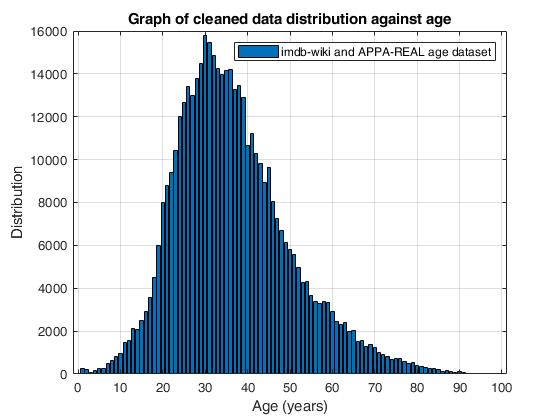

lim_age = numel(unique(age));
plot_age = zeros;
for index = 1:lim_age
    i = index-1;
    plot_age(index) = length(find(age(:)==i));
end

fig1 = figure();

% plot age
bar((0:100),plot_age)

% set a title and key (legend) for the figure
title('Graph of cleaned data distribution against age'); %title
legend('imdb-wiki and APPA-REAL age dataset','Location','northeast');
%label axes
xlabel('Age (years)'); % x-axis label
ylabel('Distribution'); % y-axis label
grid on;                    %enable grid on the graph

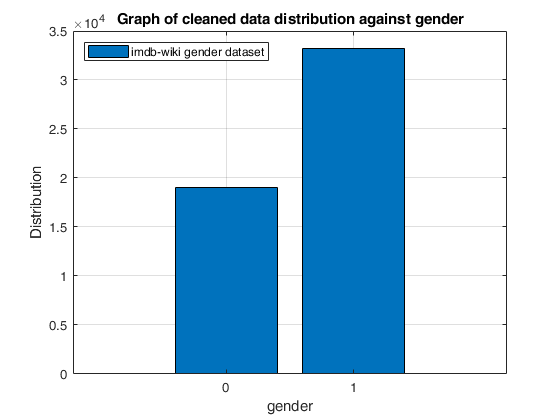

lim_gen = numel(unique(gender));
plot_gender = zeros;
for index = 1:lim_gen
    i = index-1;
    plot_gender(index) = length(find(gender(:)==i));
end
fig2 = figure();

bar((0:1),plot_gender)
title('Graph of cleaned data distribution against gender');
legend('imdb-wiki gender dataset','Location','northwest');
xlabel('gender');
ylabel('Distribution');
grid on;

[~,idx] = sort(wiki_imdb_gender_fc,'descend');
wiki_imdb_gender_fc = wiki_imdb_gender_fc(idx);
full_path_gender = full_path_gender(idx);
gender = gender(idx);

try
    final_gender_file = load(['data' filesep 'final_gender.mat']);
    final_gender_fc = final_gender_file.final_gender_fc;
    final_gender_path = final_gender_file.final_gender_path;
    final_gendr = final_gender_file.final_gendr;
catch ME    
    % picked data
    final_gender_fc = zeros;
    final_gender_path = {zeros};
    final_gendr = zeros;
    
    % dropped data
    final_gender_fc_0 = zeros;
    final_gender_path_0 = {zeros};
    final_gendr_0 = zeros;
        
    num_images = 15000;
    A_limit = numel(unique(gender));
    A = zeros(1,A_limit);
    i = 0;
    j = 0;
    for indx_red = 1:A_limit
        indx = indx_red-1;
        for index = 1:numel(wiki_imdb_gender_fc)
            if gender(index)==indx && A(indx_red)<num_images
                A(indx_red) = A(indx_red) + 1;
                i=i+1;
                final_gender_fc(i) = wiki_imdb_gender_fc(index);
                final_gender_path(i) = full_path_gender(index);
                final_gendr(i) = gender(index);
            elseif gender(index)==indx && A(indx_red)>=num_images
                j=j+1;
                final_gender_fc_0(j) = wiki_imdb_gender_fc(index);
                final_gender_path_0(j) = full_path_gender(index);
                final_gendr_0(j) = gender(index);
            end
        end
    end
    save(strcat(['data' filesep 'final_gender.mat']),'final_gender_fc_0','final_gender_path_0','final_gendr_0','final_gender_fc','final_gender_path','final_gendr');
end

[~,idx] = sort(face_score,'descend');
face_score = face_score(idx);
paths = paths(idx);
age = age(idx);

try
    final_age_file = load(['data' filesep 'final_age.mat']);
    final_age_fc = final_age_file.final_age_fc;
    final_age_path = final_age_file.final_age_path;
    final_ag = final_age_file.final_ag;
catch ME
    
    % picked data
    final_age_fc = zeros;
    final_age_path = {zeros};
    final_ag = zeros;
    
    % dropped data
    final_age_fc_0 =zeros;
    final_age_path_0 ={zeros};
    final_ag_0 =zeros;
    
    num_images = 1500;
    A_limit = numel(unique(age));
    A = zeros(1,A_limit);
    i = 0;
    j = 0;
    for indx_red = 1:A_limit
        for index = 1:numel(face_score)
            if age(index)==indx_red
                if A(indx_red)<num_images
                    A(indx_red) = A(indx_red) + 1;
                    i=i+1;
                    final_age_fc(i) = face_score(index);
                    final_age_path(i) = paths(index);
                    final_ag(i) = age(index);
                elseif age(index)==indx_red && A(indx_red)>=num_images
                    j=j+1;
                    final_age_fc_0(j) = face_score(index);
                    final_age_path_0(j) = paths(index);
                    final_ag_0(j) = age(index);
                end
            end
        end
    end
    save(strcat(['data' filesep 'final_age.mat']),'final_age_fc_0','final_age_path_0','final_ag_0','final_age_fc','final_age_path','final_ag');
end

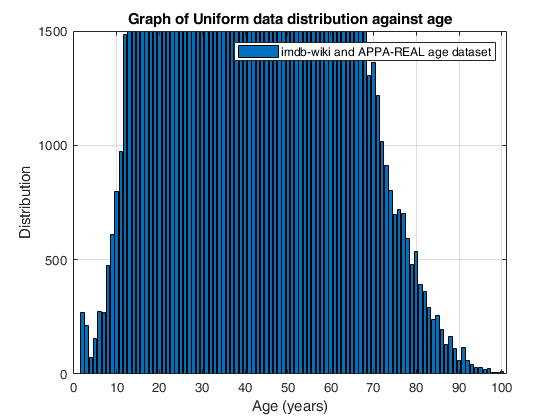

lim_age = numel(unique(final_ag));
plot_age = zeros;
for index = 1:lim_age
    i = index-1;
    plot_age(index) = length(find(final_ag(:)==i));
end

fig1 = figure();

% plot age
bar((1:lim_age),plot_age)

% set a title and key (legend) for the figure
title('Graph of Uniform data distribution against age'); %title
legend('imdb-wiki and APPA-REAL age dataset','Location','northeast');
%label axes
xlabel('Age (years)'); % x-axis label
ylabel('Distribution'); % y-axis label
grid on;                    %enable grid on the graph

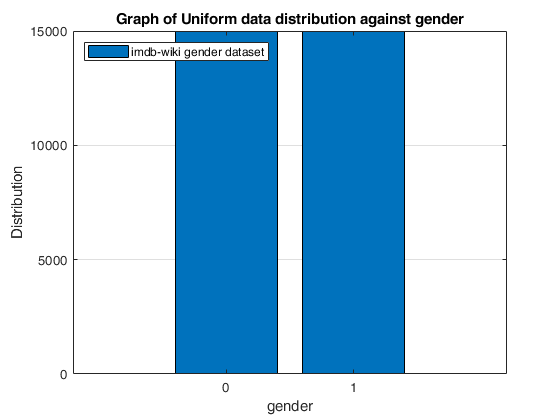

lim_gen = numel(unique(final_gendr));
plot_gender = zeros;
for index = 1:lim_gen
    i = index-1;
    plot_gender(index) = length(find(final_gendr(:)==i));
end
fig2 = figure();

bar((0:1),plot_gender)
title('Graph of Uniform data distribution against gender');
legend('imdb-wiki gender dataset','Location','northwest');
xlabel('gender');
ylabel('Distribution');
grid on;

## CREATE AN IMAGE DATA STORE

- Define the dataStore and show an image preview

try
    % try to read files if created before
    imds = load(['data' filesep 'imds.mat']);
    imds_age = imds.imds_age;
    imds_gender = imds.imds_gender;
catch 
    imds_gender = imageDatastore(final_gender_path,'Labels',categorical(final_gendr));
    imds_age = imageDatastore(final_age_path,'Labels',categorical(final_ag));
    imds_gender = imds_gender.shuffle;
    imds_age = imds_age.shuffle;
    save(strcat(['data' filesep 'imds.mat']), 'imds_age','imds_gender');
end

try
    % try to read files if created before
    imds = load(['data' filesep 'splited_imds.mat']);
    imdsAgeVal = splited_imds.imdsAgeVal;
    imdsAgeTst = splited_imds.imdsAgeTst;
    imdsAgeTrn = splited_imds.imdsAgeTrn;
    imdsGenderVal = splited_imds.imdsGenderVal;
    imdsGenderTst = splited_imds.imdsGenderTst;
    imdsGenderTrn = splited_imds.imdsGenderTrn;
catch 
    [imdsAgeVal,imdsAgeTst,imdsAgeTrn] = splitEachLabel(imds_age,0.1,0.1,'randomize');
    [imdsGenderVal,imdsGenderTst,imdsGenderTrn] = splitEachLabel(imds_gender,0.1,0.1,'randomize');
    save(strcat(['data' filesep 'splited_imds.mat']), 'imdsAgeVal','imdsAgeTst','imdsAgeTrn','imdsGenderVal','imdsGenderTst','imdsGenderTrn');
end

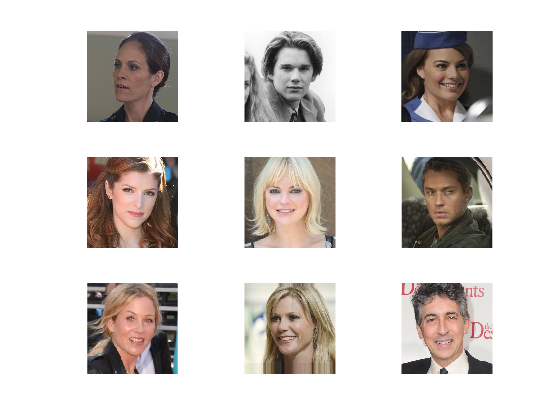

numImages = numel(imdsGenderTrn.Files);
perm = randperm(numImages,9);
for i = 1:9
    subplot(3,3,i);
    imshow(imdsGenderTrn.Files{perm(i)});
end

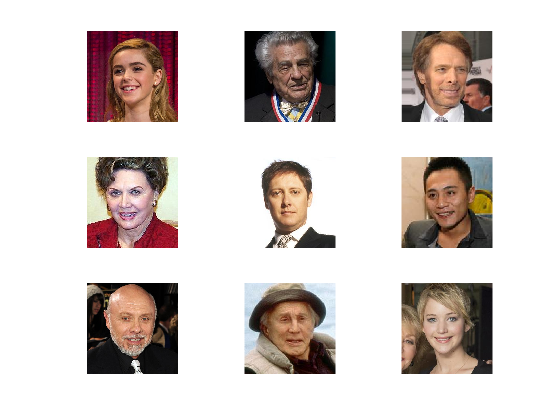

numImages = numel(imdsAgeTrn.Files);
perm = randperm(numImages,9);
for i = 1:9
    subplot(3,3,i);
    imshow(imdsAgeTrn.Files{perm(i)});
end

try
    augmented_Image_Datastore = load(['data' filesep 'augmented_Image_Datastore.mat']);
    imdsAgeValidation = augmented_Image_Datastore.imdsAgeValidation;
    imdsAgeTrain = augmented_Image_Datastore.imdsAgeTrain;
    imdsAgeTest = augmented_Image_Datastore.imdsAgeTest
    imdsGenderTrain = augmented_Image_Datastore.imdsGenderTrain;
    imdsGenderTest = augmented_Image_Datastore.imdsGenderTest
    imdsGenderValidation = augmented_Image_Datastore.imdsGenderValidation;    
catch ME
    imageSize = [224 224 3];
    imdsAgeValidation = augmentedImageDatastore(imageSize,imdsAgeVal,'ColorPreprocessing','gray2rgb');
    imdsAgeTrain = augmentedImageDatastore(imageSize,imdsAgeTrn,'ColorPreprocessing','gray2rgb')
    imdsAgeTest = augmentedImageDatastore(imageSize,imdsAgeTst,'ColorPreprocessing','gray2rgb');
    imdsGenderTrain = augmentedImageDatastore(imageSize,imdsGenderTrn,'ColorPreprocessing','gray2rgb')
    imdsGenderTest = augmentedImageDatastore(imageSize,imdsGenderTst,'ColorPreprocessing','gray2rgb');
    imdsGenderValidation = augmentedImageDatastore(imageSize,imdsGenderVal,'ColorPreprocessing','gray2rgb');
    
    save(strcat(['data' filesep 'augmented_Image_Datastore.mat']),'imdsAgeValidation','imdsAgeTrain','imdsAgeTest','imdsGenderTrain','imdsGenderTest','imdsGenderValidation');
end

imdsAgeTrain =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 796
        DataAugmentation: 'none'
      ColorPreprocessing: 'gray2rgb'
              OutputSize: [224 224]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


imdsGenderTrain =   augmentedImageDatastore with properties:

           MiniBatchSize: 128
         NumObservations: 400
        DataAugmentation: 'none'
      ColorPreprocessing: 'gray2rgb'
              OutputSize: [224 224]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## **SECTION D: DEFINE **NETWORK LAYERS AND TRAINING PARAMETERS

Layers

- convolution2dLayer(96,96,options);

- imageInputLayer(inputSize = [height, width, and number of channels],options)

- fullyConnectedLayer(outputSize,options);

- maxPooling2dLayer(poolSize,options);

- reluLayer(options);

- convolution2dLayer(96,96,options)

- averagePooling2dLayer(poolSize,options);

- softmaxLayer(options)

- classificationLayer(options)

num_filters = 64;
layers = [
    imageInputLayer([227 227 3],'Name','input')
    
    convolution2dLayer(3,num_filters,'Stride',1,'NumChannels',3,'Padding',1,'Name','conv1_1')
    reluLayer('Name','relu1_1')
    convolution2dLayer(3,num_filters,'Stride',1,'NumChannels',num_filters,'Padding',1,'Name','conv1_2')
    reluLayer('Name','relu1_2')
    maxPooling2dLayer(2,'Stride',2,'Name','pool1')
    
    convolution2dLayer(3,num_filters*2,'Stride',1,'NumChannels',num_filters,'Padding',1,'Name','conv2_1')
    reluLayer('Name','relu2_1')
    convolution2dLayer(3,num_filters*2,'Stride',1,'NumChannels',num_filters*2,'Padding',1,'Name','conv2_2')
    reluLayer('Name','relu2_2')
    maxPooling2dLayer(2,'Stride',2,'Name','pool2')
    
    convolution2dLayer(3,num_filters*4,'Stride',1,'NumChannels',num_filters*2,'Padding',1,'Name','conv3_1')
    reluLayer('Name','relu3_1')
    convolution2dLayer(3,num_filters*4,'Stride',1,'NumChannels',num_filters*4,'Padding',1,'Name','conv3_2')
    reluLayer('Name','relu3_2')
    convolution2dLayer(3,num_filters*4,'Stride',1,'NumChannels',num_filters*4,'Padding',1,'Name','conv3_3')
    reluLayer('Name','relu3_3')
    maxPooling2dLayer(2,'Stride',2,'Name','pool3')
    
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*4,'Padding',1,'Name','conv4_1')
    reluLayer('Name','relu4_1')
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*8,'Padding',1,'Name','conv4_2')
    reluLayer('Name','relu4_2')
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*8,'Padding',1,'Name','conv4_3')
    reluLayer('Name','relu4_3')
    maxPooling2dLayer(2,'Stride',2,'Name','pool4')
    
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*8,'Padding',1,'Name','conv5_1')
    reluLayer('Name','relu5_1')
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*8,'Padding',1,'Name','conv5_2')
    reluLayer('Name','relu5_2')
    convolution2dLayer(3,num_filters*8,'Stride',1,'NumChannels',num_filters*8,'Padding',1,'Name','conv5_3')
    reluLayer('Name','relu5_3')
    maxPooling2dLayer(2,'Stride',2,'Name','pool5')
    
    fullyConnectedLayer(num_filters*num_filters,'Name','fc6') 
    reluLayer('Name','relu6')
    dropoutLayer(0.5,'Name','drop6')
    
    fullyConnectedLayer(num_filters*num_filters,'Name','fc7')
    reluLayer('Name','relu7')
    dropoutLayer(0.5,'Name','drop7')
    
    fullyConnectedLayer(101,'Name','fc8-101')
    
    softmaxLayer('Name','prob')
    classificationLayer('Name','output')];

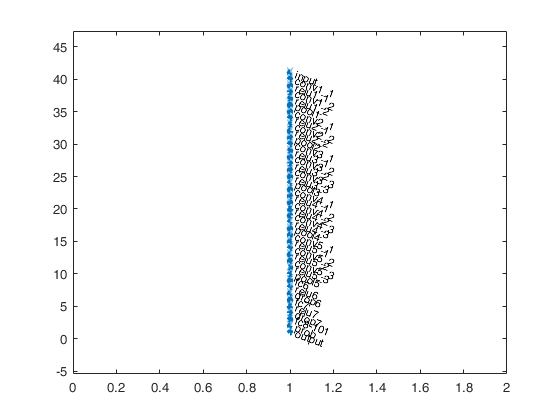

lgraph = layerGraph(layers);
figure
plot(lgraph)

layers_Age = lgraph

layers_Age =   LayerGraph with properties:

         Layers: [41×1 nnet.cnn.layer.Layer]
    Connections: [40×2 table]


layers_Age.Layers

ans =   41x1 Layer array with layers:

     1   'input'     Image Input             227x227x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   

larray = fullyConnectedLayer(2,'Name','fc8-2');
layers_Gender = replaceLayer(lgraph,'fc8-101',larray)

layers_Gender =   LayerGraph with properties:

         Layers: [41×1 nnet.cnn.layer.Layer]
    Connections: [40×2 table]


layers_Gender.Layers

ans =   41x1 Layer array with layers:

     1   'input'     Image Input             227x227x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   

# **Configure Training Options**

Set Up Parameters and Train Convolutional Neural Network

CheckpointPathAge = ['data' filesep 'trainCheckpoints' filesep 'Age'];
options_Age = trainingOptions(...
    ...Specify Solver and Maximum Number of Epochs
    'sgdm', ...
    'Shuffle','every-epoch', ...
    'MaxEpochs',3, ...
    ...
    ... Specify Validation Data
    'ValidationData',imdsAgeValidation, ...
    'InitialLearnRate',0.0001, ...
    'ValidationFrequency',5, ...
    ...
    ... Save Checkpoint Networks and Resume Training
    'CheckpointPath',CheckpointPathAge,...
    ...
    'Plots','training-progress', ...
    'VerboseFrequency',5, ...
    'Verbose', true)

options_Age =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-04
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 3
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 5
               ValidationData: [1×1 augmentedImageDatastore]
          ValidationFrequency: 5
           ValidationPatience: 5
                      Shuffle: 'every-epoch'
               CheckpointPath: 'data\trainCheckpoints\Age'
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'training-progress'
               SequenceLength: 'longest'
         SequencePaddingValue: 0


CheckpointPathGender = ['data' filesep 'trainCheckpoints' filesep 'Gender'];
options_Gender = trainingOptions(...
    ...Specify Solver and Maximum Number of Epochs
    'sgdm', ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',0.0001, ...
    'MaxEpochs',10, ...
    ...
    ... Specify Validation Data
    'ValidationData',imdsGenderValidation, ...
    'ValidationFrequency',5, ...
    ...
    ... Save Checkpoint Networks and Resume Training
    'CheckpointPath',CheckpointPathGender,...
    ...
    'Plots','training-progress', ...
    'VerboseFrequency',5, ...
    'Verbose', true)

options_Gender =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-04
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 10
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 5
               ValidationData: [1×1 augmentedImageDatastore]
          ValidationFrequency: 5
           ValidationPatience: 5
                      Shuffle: 'every-epoch'
               CheckpointPath: 'data\trainCheckpoints\Gender'
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'training-progress'
               SequenceLength: 'longest'
         SequencePaddingValue: 0


checkpoint_Age = getlatestfile(CheckpointPathAge);
checkpoint_Gender = getlatestfile(CheckpointPathGender);

Resuming training from Last checkpoint ... 


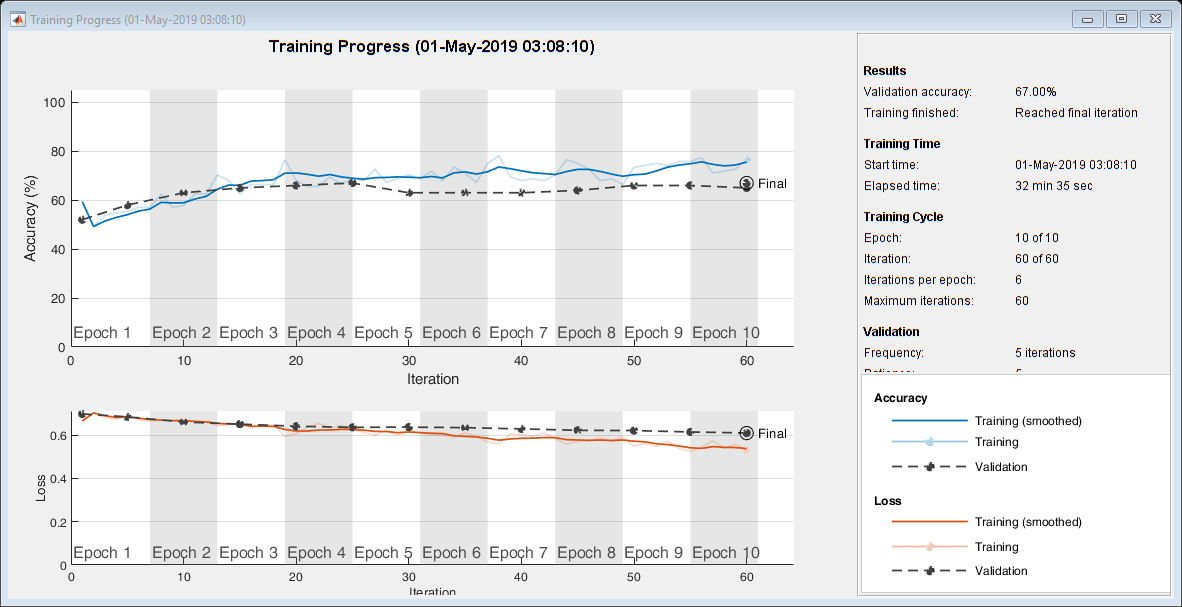

Training on single CPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:31 |       59.38% |       52.00% |       0.6658 |       0.6983 |      1.0000e-04 |
|       1 |           5 |       00:02:46 |       55.47% |       58.00% |       0.6878 |       0.6850 |      1.0000e-04 |
|       2 |          10 |       00:05:36 |       57.81% |       63.00% |       0.6705 |       0.6609 |      1.0000e-04 |
|       3 |          15 |       00:08:24 |       62.50% |       65.00% |       0.6567 |       0.6513 |      1.0000e-04 

try
    load(fullfile(CheckpointPathGender,checkpoint_Gender),'net');
    disp('Resuming training from Last checkpoint ... ')
    net_Gender = trainNetwork(imdsGenderTrain,net.Layers, options_Gender);
catch ME
    disp('New training ... ')
    net_Gender = trainNetwork(imdsGenderTrain,layers_Gender, options_Gender);
    save(strcat(['data' filesep 'trained' filesep 'net_Gender.mat']), 'net_Gender');
end

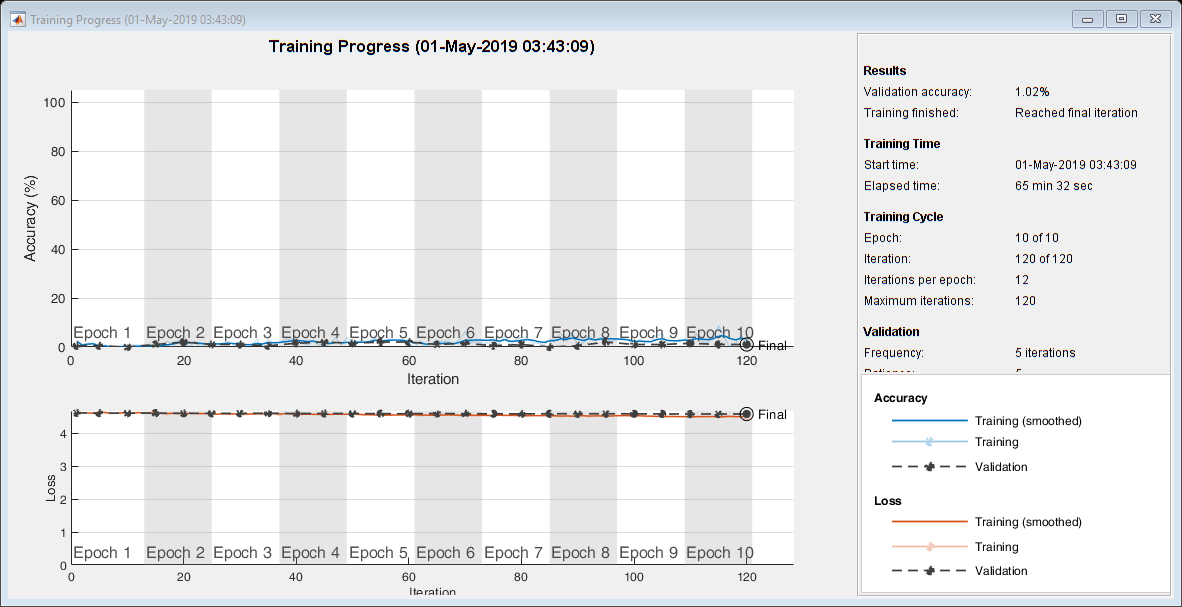

Training on single CPU.


Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:30 |        2.34% |        0.51% |       4.6379 |       4.6262 |      1.0000e-04 |
|       1 |           5 |       00:02:47 |        0.00% |        0.51% |       4.6744 |       4.6220 |      1.0000e-04 |
|       1 |          10 |       00:05:29 |        0.78% |        0.00% |       4.6181 |       4.6194 |      1.0000e-04 |
|       2 |          15 |       00:08:17 |        0.78% |        1.02% |       4.6302 |       4.6196 |      1.0000e-04 

try
    load(fullfile(CheckpointPathAge,checkpoint_Age),'net');
    net_Age = trainNetwork(imdsAgeTrain,net.Layers, options_Age);
catch ME
    clear('net_Age')
    net_Age = trainNetwork(imdsAgeTrain,layers_Age, options_Age);
    save(strcat(['data' filesep 'trained' filesep 'net_Age.mat']), 'net_Age');
end

# **Evaluate Model Using Test Set**

YPred_Age = int8(classify(net_Age,imdsAgeTest));
YTest_Age = int8(imdsAgeTst.Labels);
YPred_Gender = int8(classify(net_Gender,imdsGenderTest));
YTest_Gender = int8(imdsGenderTst.Labels);

net_Gender_accuracy = 0.8000

Actual | Predicted 


ans = 10×2 int8 matrix
   2   2
   1   2
   2   2
   2   2
   1   1
   1   1
   2   2
   2   2
   1   1
   2   1


net_Age_accuracy = 0.0100

Actual Age | Predicted Age


ans = 10×2 int8 matrix
   84   32
    8   10
   31   32
   13   25
   78   30
   29   25
   71   38
   82   58
   85   64
   17   23


try
    net_Gender_accuracy = sum(YPred_Gender == YTest_Gender)/numel(YTest_Gender)

net_Age =   SeriesNetwork with properties:

    Layers: [41×1 nnet.cnn.layer.Layer]


    disp('Actual | Predicted ')
    [YTest_Gender(1:10,:) YPred_Gender(1:10,:)]

net_Gender =   SeriesNetwork with properties:

    Layers: [41×1 nnet.cnn.layer.Layer]


    net_Age_accuracy = sum(YPred_Age == YTest_Age)/numel(YTest_Age)
    disp('Actual Age | Predicted Age')
    [YTest_Age(1:10,:) YPred_Age(1:10,:)]
catch 
end

# Load The Pretrained Network

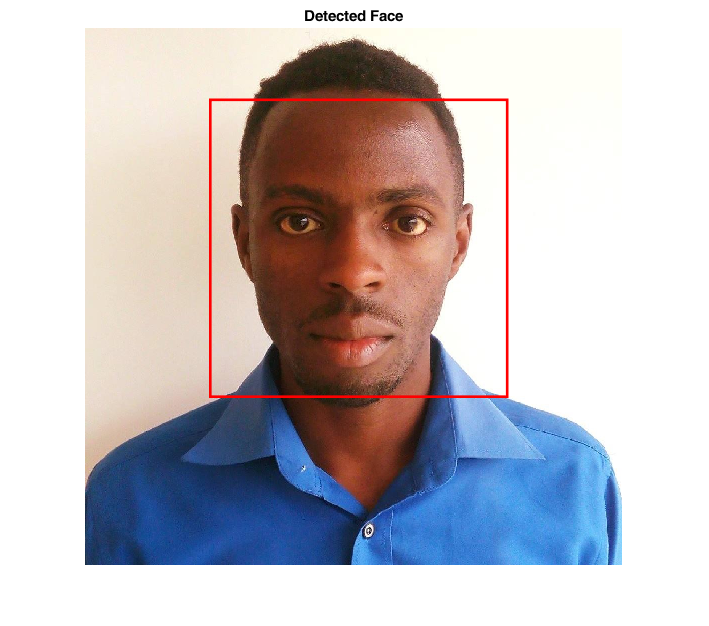

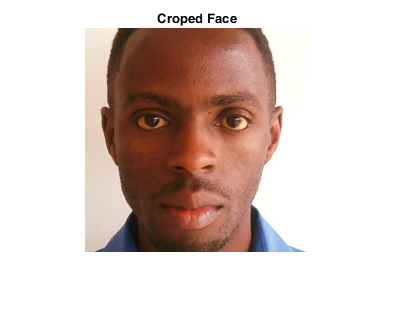

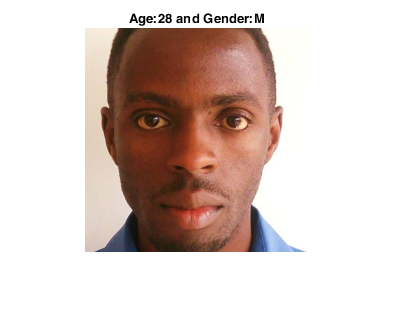

load('data\trained\net_Age.mat','net');
net_Age = net
load('data\trained\net_Gender.mat','net');
net_Gender = net

# Predict Age and Gender

[img_name, img_folder] = uigetfile ({'*.jpg';'*.jpeg';'*.bmp';'*.png'}, 'File Selector');
img_path = fullfile(img_folder, img_name);
inputSize = [224 224];
try
    img = imread(img_path);
    X = size(img);
    face_detector = vision.CascadeObjectDetector; 
    face_detector.MergeThreshold = 7 ;
    faces_detected = step(face_detector, img); 
    figure;
    imshow(img);
    pad = X(1)/30;
    dim = faces_detected(1,:);
    dim = [dim(1)-pad dim(2)-pad dim(3)+2*pad dim(4)+2*pad];
    rectangle('Position', dim, 'LineWidth', 2, 'LineStyle', '-', 'EdgeColor', 'r');
    title('Detected Face')
    croped_img = imcrop(img, dim); 
    img = imresize(croped_img,inputSize);
    figure;
    imshow(img);
    title('Croped Face')
    
    gender_ref = ['F','M'];
    label_Gender = gender_ref(int8(net_Gender.classify(img)));
    label_Age = int8(net_Age.classify(img));
    
    figure;
    imshow(img);
    title(strcat('Age: ',num2str(label_Age),' and Gender: ',num2str(label_Gender))); 
catch ME
    disp(ME.message)
end

# **Reusable Functions**

function[ar_fc,file_path,real_age] = ar_name_label(root_directory,folder,label)
    label = char(label);
    folder = char(folder);
    
    % read csv file
    files_dir_csv = fullfile(root_directory, label);
    csv_file_table = readtable(files_dir_csv);
    real_age = csv_file_table.real_age;
    real_age = real_age';
    
    % read jpeg files
    filePattern = fullfile(root_directory, folder,'*.jpg_face.jpg');
    jpegFiles = dir(filePattern);
    baseFileName = {jpegFiles.name};
    file_path = fullfile(root_directory,folder,baseFileName);
    
    % read the face score data
    ar_fc = cell(0);
    for index = 1:numel(jpegFiles)
        ar_fc{index} = ar_metadata(root_directory,folder,jpegFiles(index));
    end
end

function[fc] = ar_metadata(root_directory,folder,file)
    file_name = file.name;
    split_file_name = strsplit(file_name,'.');
    d = char(split_file_name(1));
    mat_file = load(fullfile(root_directory,folder,strcat(d,'.jpg.mat')));
    fc= mat_file.fileinfo.main_face_score;
end
function[cln_age,wiki_imdb_path,fc_age,cln_gender,full_path_gender,fc_gender] = clean_imdb_wiki(age,gender,fc,full_path)
    try
        imdb_wiki_cleaning = load(['data' filesep 'claning' filesep 'imdb_wiki_cleaning.mat']);
        ind = imdb_wiki_cleaning.index;
        cln_gender = imdb_wiki_cleaning.cln_gender;
        fc_gender = imdb_wiki_cleaning.fc_gender;
        full_path_gender = imdb_wiki_cleaning.full_path_gender;
        cln_age = imdb_wiki_cleaning.cln_age;
        fc_age = imdb_wiki_cleaning.fc_age;
        wiki_imdb_path = imdb_wiki_cleaning.wiki_imdb_path;
        i = imdb_wiki_cleaning.i;
        j = imdb_wiki_cleaning.j;
        disp('resumed cleaning imdb_wiki ...')
    catch
        ind = 0;
        cln_age = zeros;
        cln_gender = zeros;
        fc_gender = zeros;
        fc_age = zeros;
        full_path_gender = {zeros};
        wiki_imdb_path = {zeros};
        i = 0;
        j = 0;
        disp('start cleaning imdb_wiki ...')
    end
    time_taken = 0;
    temp_gender = isnan(gender);
    tic
    for index = 1:numel(temp_gender)
        if index>ind
            % Pick on images with faces only
            if isfinite(fc(index))
                try
                    % Pick on items with known gender only
                    if ~temp_gender(index)
                        % Pick on items which exist in the directory only
                        if isfile(char(full_path(index)))
                            % Pick on items whichare readable
                            if imread(char(full_path(index)))
                                i=i+1;
                                fc_gender(i) = fc(index);
                                cln_gender(i) = gender(index);
                                full_path_gender(i) = full_path(index);
                            end
                        end
                    end
                    % Pick on items with age from 0 to 100
                    if age(index)>=0 && age(index)<=100
                        % Pick on items which exist in the directory only
                        if isfile(char(full_path(index)))
                            try
                                imread(char(full_path(index)));
                                j=j+1;
                                fc_age(j) = fc(index);
                                cln_age(j) = age(index);
                                wiki_imdb_path(j) = full_path(index);
                            catch
                            end
                        end
                    end
                catch ME
                    fprintf('%s %s %d',ME.message,full_path(index),index)
                end
            end
        end
        if endsWith(num2str(index),'5000')
            prnt_pct = int8(100*index/numel(temp_gender));
            time_t = toc/60;
            time_taken = time_taken + time_t;
            fprintf('imdb-wiki cleaning done %d %% in time %d minutes \n',prnt_pct,int8(time_taken))
            save(strcat(['data' filesep 'claning' filesep 'imdb_wiki_cleaning.mat']), 'index','i','j','fc_age','cln_age','wiki_imdb_path','cln_gender','fc_gender','full_path_gender');
        end
    end
    fprintf('imdb-wiki cleaning done 100 %% \n')
end

function [cln_age,ar_path,fc_age] = clean_ar_data(age,fc,full_path)
    try
        appa_real_cleaning = load(['data' filesep 'claning' filesep 'appa_real_cleaning.mat']);
        ind = appa_real_cleaning.index;
        i = appa_real_cleaning.i;
        fc_age = appa_real_cleaning.fc_age;
        cln_age = appa_real_cleaning.cln_age;
        ar_path = appa_real_cleaning.ar_path;
        disp('resumed cleaning appa_real ...')
    catch
        ind = 0;
        cln_age = zeros;
        fc_age = zeros;
        ar_path = {zeros};
        i = 0;
        disp('start cleaning appa_real ...')
    end
    time_taken = 0;
    tic
    for index = 1:numel(age)
        if index>ind
            % Pick on images with faces only
            if isfinite(fc(index))
                try
                    % Pick on items with age from 0 to 100
                    if age(index)>=0 && age(index)<=100
                        % Pick on items which exist in the directory only
                        if isfile(char(full_path(index)))
                            try
                                imread(char(full_path(index)));
                                i=i+1;
                                fc_age(i) = fc(index);
                                cln_age(i) = age(index);
                                ar_path(i) = full_path(index);
                            catch
                            end
                        end
                    end
                catch ME
                    fprintf('%s %s %d',ME.message,full_path(index),index)
                end
            end
        end
        if endsWith(num2str(index),'000')
            prnt_pct = int8(100*index/numel(age));
            time_t = toc/60;
            time_taken = time_taken + time_t;
            fprintf('appa-real cleaning done %d %% in time %d minutes \n',prnt_pct,int8(time_taken))
            save(strcat(['data' filesep 'claning' filesep 'appa_real_cleaning.mat']), 'index','i','fc_age','cln_age','ar_path');
        end
    end
    fprintf('appa-real cleaning done 100 %% \n')
end

function latestfile = getlatestfile(directory)
    % This returns the latest file from the directory
    % get the directory contents
    dirc = dir(directory);
    % Filter out all the folders.
    dirc = dirc(~cellfun(@isfolder,{dirc(:).name}));
    % I contains the index to the biggest number which is the latest file
    [~,I] = max([dirc(:).datenum]);
    if ~isempty(I)
        latestfile = dirc(I).name;
    else
        latestfile = false;
    end
end